folder = "D:\Whale Data\Raw Audio Data\CaseyIslands2017\detectors";
dsname = "CaseyIslands2017";

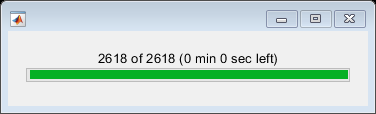

det = Detector(dsname, 1);
det.detections();

detectors = load(folder + "\\detectors.mat").D;

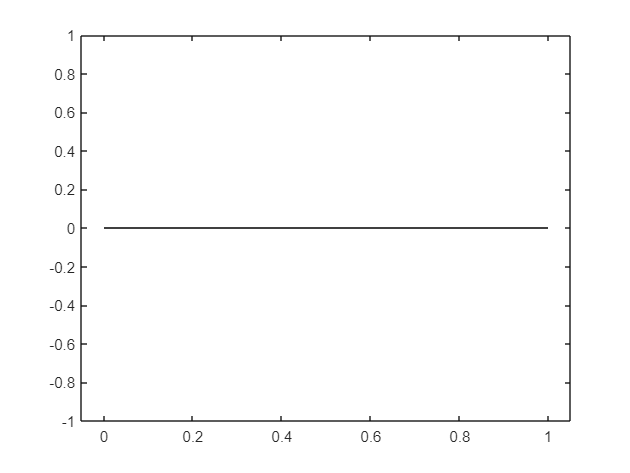

deltas = arrayfun(@(d) d.mu_n - d.mu_s, [detectors.segmmwhite]);
deltalimwhite = prctile(deltas, 50);
figure
histogram(deltas)

deltas = arrayfun(@(d) d.mu_n - d.mu_s, [detectors.segmm]);
deltalim = prctile(deltas, 50);
figure
histogram(deltas)

de = arrayfun(@(d) max(d.probs) - min(d.probs), [detectors.bledwhite]);

histogram(de)

labels = [];
psegmmwhite = [];
psegmmwhitegauss = [];
psegmm = [];
ebledwhite = [];
ebled = [];
downsample = 3;
for i = 1:numel(detectors)
    d = detectors(i);
    segmmwhite = d.segmmwhite;
    segmmwhitegauss = d.segmmwhitegauss;
    segmm = d.segmm;
    bledwhite = d.bledwhite;
    bled = d.bled;
    if ~all(d.truelabels == 0)   
    psegmmwhitegauss = [psegmmwhitegauss, segmmwhitegauss.probs(1:downsample:end) * segmmwhitegauss.converged];
    psegmmwhite = [psegmmwhite, segmmwhite.probs(1:downsample:end) * segmmwhite.converged];
    psegmm = [psegmm, segmm.probs(1:downsample:end) * segmm.converged];
    ebledwhite = [ebledwhite, bledwhite.probs(1:downsample:end)];
    ebled = [ebled, bled.probs(1:downsample:end)];
    labels = [labels, d.truelabels(1:downsample:end)];
    end
end

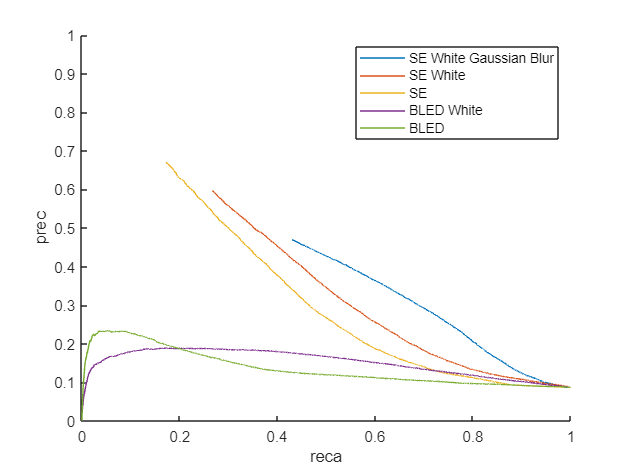


xc = 'reca';
yc = 'prec';
xlims = [0, 1];
ylims = [0, 1];

% idx = labels == 1;

figure
hold on
[x, y] = perfcurve(labels, psegmmwhitegauss, 1, 'XCrit',xc, 'YCrit',yc);
plot(x, y)
[x, y] = perfcurve(labels, psegmmwhite, 1, 'XCrit',xc, 'YCrit',yc);
plot(x, y)
[x, y] = perfcurve(labels, psegmm, 1, 'XCrit',xc, 'YCrit',yc);
plot(x, y)
[x, y] = perfcurve(labels, ebledwhite, 1, 'XCrit',xc, 'YCrit',yc);
plot(x, y)
[x, y] = perfcurve(labels, ebled, 1, 'XCrit',xc, 'YCrit',yc);
plot(x, y)
hold off
legend("SE White Gaussian Blur", "SE White", "SE", "BLED White", "BLED")
xlabel(xc)
ylabel(yc)
xlim(xlims);
ylim(ylims)

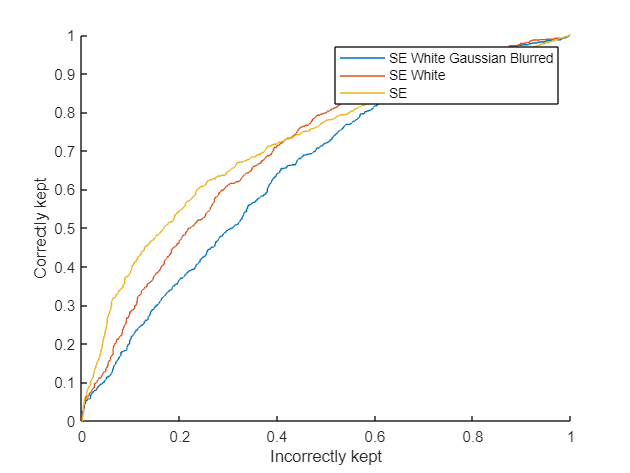

discardwhitegauss = arrayfun(@(d) (d.mu_n - d.mu_s)*d.converged, [detectors.segmmwhitegauss]);
discardwhite = arrayfun(@(d) (d.mu_n - d.mu_s)*d.converged, [detectors.segmmwhite]);
discard = arrayfun(@(d) (d.mu_n - d.mu_s)*d.converged, [detectors.segmm]);
truediscard = cellfun(@(y) any(y), {detectors.truelabels});

xc = 'fpr';
yc = 'tpr';

figure
hold on
[x, y] = perfcurve(truediscard, discardwhitegauss, 1, 'XCrit',xc, 'YCrit',yc);
plot(x, y)
[x, y] = perfcurve(truediscard, discardwhite, 1, 'XCrit',xc, 'YCrit',yc);
plot(x, y)
[x, y] = perfcurve(truediscard, discard, 1, 'XCrit',xc, 'YCrit',yc);
plot(x, y)
hold off
legend("SE White Gaussian Blurred","SE White", "SE")
xlabel("Incorrectly kept")
ylabel("Correctly kept")

hassignal = cellfun(@(y) any(y), {detectors.truelabels});
names = ["segmmwhitegauss", "segmmwhite", "segmm", "bledwhite", "bled"];
%get the stats of non-converged files that contain signal
for name = names(1:3)
    name
    conv = arrayfun(@(r) r.(name).converged, detectors);
    notconvsignal = hassignal & ~conv;
    numnotconv = sum(notconvsignal)
    pnotconv = sum(notconvsignal)/sum(hassignal)
    nummissedcalls = sum(arrayfun(@(r) size(r.annotations, 1), detectors(notconvsignal)))
    totalcalls = sum(arrayfun(@(r) size(r.annotations, 1), detectors))
    pmissedcalls = nummissedcalls/totalcalls
end

name = "segmmwhitegauss"

numnotconv = 8

pnotconv = 0.0071

nummissedcalls = 17

totalcalls = 3393

pmissedcalls = 0.0050

name = "segmmwhite"

numnotconv = 11

pnotconv = 0.0098

nummissedcalls = 13

totalcalls = 3393

pmissedcalls = 0.0038

name = "segmm"

numnotconv = 153

pnotconv = 0.1356

nummissedcalls = 369

totalcalls = 3393

pmissedcalls = 0.1088


rocdetectors = detectors(hassignal);
thresh.segmmwhitegauss = linspace(0.05,0.9, 20);
thresh.segmmwhite = linspace(0.05,0.99, 20);
thresh.segmm = linspace(0.05,0.99, 20);
thresh.bledwhite = linspace(1,10, 40);
thresh.bled = linspace(1,10, 20);
for name = names(1:3)
    name
    det = [rocdetectors.(name)];    
    probs = {det.probs};
    if name == "segmm" || name == "segmmwhite" || name == "segmmwhitegauss"
        conv = arrayfun(@(d) d.converged, det);
        probs = arrayfun(@(i) probs{i} * conv(i), 1:numel(probs), 'UniformOutput',false);
    end
    anns = {rocdetectors.annotations};
    labels = {rocdetectors.truelabels};
    numdet.(name) = zeros(size(thresh));
    numnoisesamples.(name) = zeros(size(thresh));
    for k = 1:numel(thresh.(name))
        r = thresh.(name)(k)
        mask = cellfun(@(p) p > r, probs, 'UniformOutput',false);
        idx = 1:numel(mask);
        ndet = sum(arrayfun(@(i) numdetections(mask{i}, anns{i}), idx));
        nnoise = sum(arrayfun(@(i) noisesamplesdet(mask{i}, labels{i}), idx));
        numdet.(name)(k) = ndet;
        numnoisesamples.(name)(k) = nnoise;
    end
end

name = "segmmwhitegauss"

r = 0.0500

r = 0.0947

r = 0.1395

r = 0.1842

r = 0.2289

r = 0.2737

r = 0.3184

r = 0.3632

r = 0.4079

r = 0.4526

r = 0.4974

r = 0.5421

r = 0.5868

r = 0.6316

r = 0.6763

r = 0.7211

r = 0.7658

r = 0.8105

r = 0.8553

r = 0.9000

name = "segmmwhite"

r = 0.0500

r = 0.0995

r = 0.1489

r = 0.1984

r = 0.2479

r = 0.2974

r = 0.3468

r = 0.3963

r = 0.4458

r = 0.4953

r = 0.5447

r = 0.5942

r = 0.6437

r = 0.6932

r = 0.7426

r = 0.7921

r = 0.8416

r = 0.8911

r = 0.9405

r = 0.9900

name = "segmm"

r = 0.0500

r = 0.0995

r = 0.1489

r = 0.1984

r = 0.2479

r = 0.2974

r = 0.3468

r = 0.3963

r = 0.4458

r = 0.4953

r = 0.5447

r = 0.5942

r = 0.6437

r = 0.6932

r = 0.7426

r = 0.7921

r = 0.8416

r = 0.8911

r = 0.9405

r = 0.9900

dets = [detectors.segmm];
conv = arrayfun(@(d) d.converged, dets);
X = arrayfun(@(d) [d.mu_n, d.mu_s, d.sigma_n, d.sigma_s, d.LL], dets, UniformOutput=false);
X = vertcat(X{:});
y = hassignal;
X = X(conv, :);
y = y(conv);
X = (X - mean(X, 1))./std(X, 1);
idxs = splitlabels(y, 0.8, "randomized");
Xtrain = X(idxs{1}, :);
ytrain = y(idxs{1});
Xtest = X(idxs{2}, :);
ytest = y(idxs{2});

clf = fitclinear(Xtrain, ytrain);
ypred = clf.predict(Xtest);
[c, order] = confusionmat(ytest, ypred)

c =    157    40
    86   109


order = 2×1 logical array
   0
   1


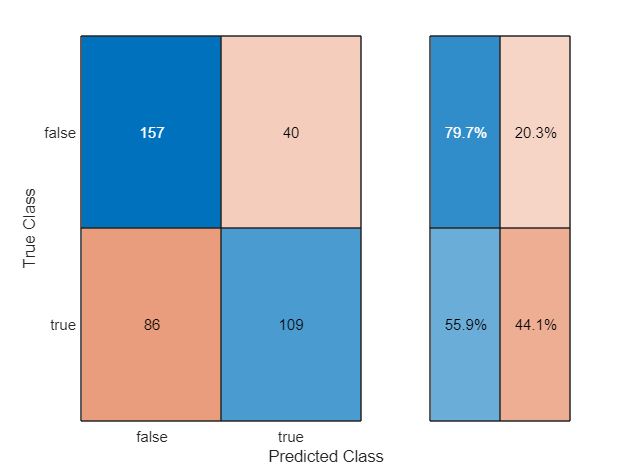

figure
confusionchart(c, order, "RowSummary","row-normalized")

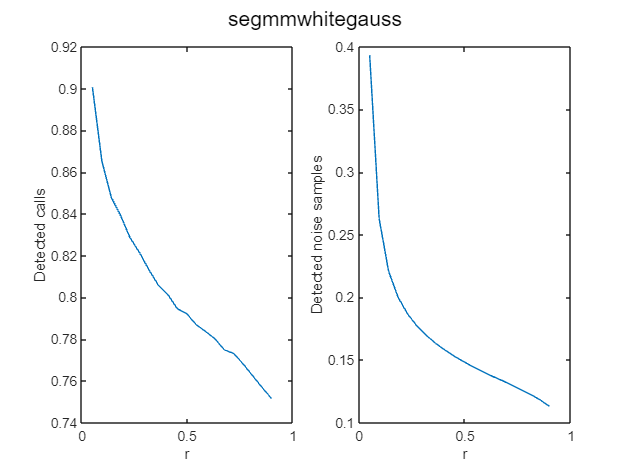

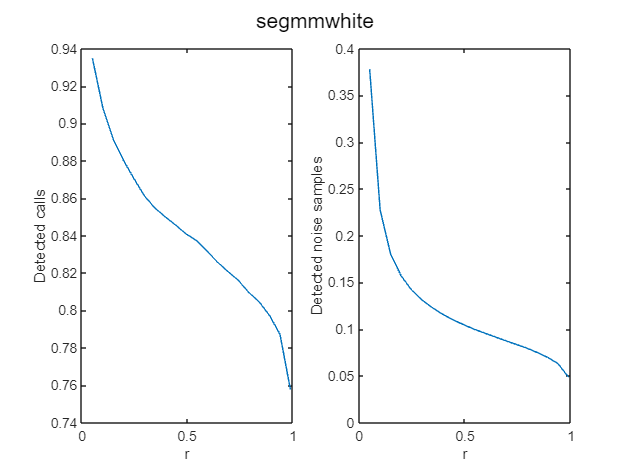

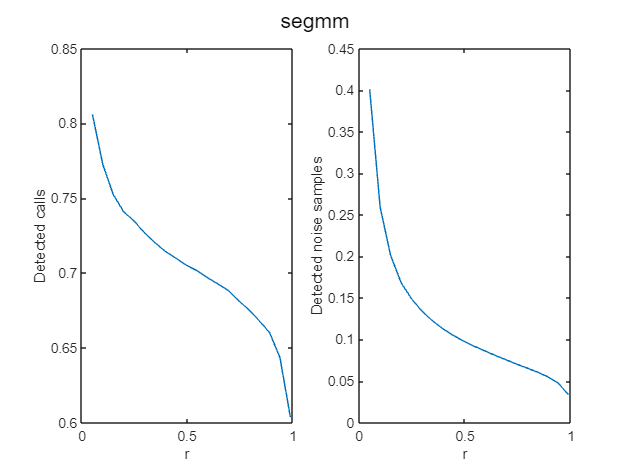

nann = sum(arrayfun(@(r) size(r.annotations, 1), rocdetectors));
nnoise = sum(arrayfun(@(r) sum(~r.truelabels), rocdetectors));
% figure
% hold on
for name = names(1:3)
    tpr = numdet.(name)/nann;
    pnoise = numnoisesamples.(name)/nnoise;
    figure
    subplot(121)
    plot(thresh.(name), tpr)
    xlabel("r")
    ylabel("Detected calls")
    subplot(122)
    plot(thresh.(name), pnoise)
    xlabel("r")
    ylabel("Detected noise samples")
    sgtitle(name)
end

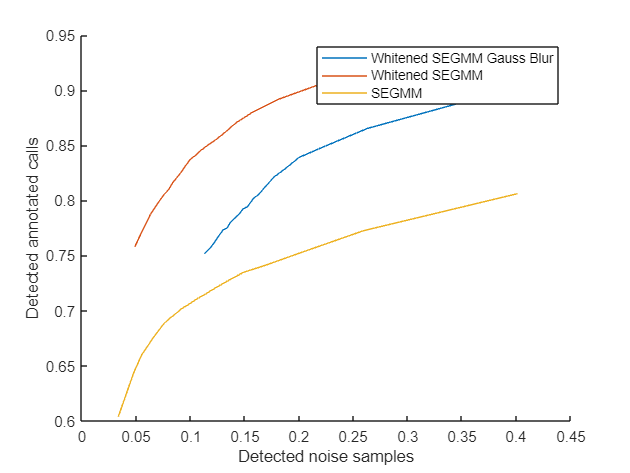

% hold off

figure
hold on
for name = names(1:3)
    tpr = numdet.(name)/nann;
    pnoise = numnoisesamples.(name)/nnoise;
    plot(pnoise, tpr)
end
hold off
legend("Whitened SEGMM Gauss Blur", "Whitened SEGMM", "SEGMM")
ylabel("Detected annotated calls")
xlabel("Detected noise samples")

function num = numdetections(mask, annotations)
    num = 0;
    for i = 1:size(annotations, 1)
        a = annotations(i, :);
        if any(mask(a.SpectrogramStartIndex : a.SpectrogramEndIndex))
            num  = num + 1;
        end
    end
end

function num = nummisses(mask, annotations)
    num = 0;
    for i = 1:size(annotations, 1)
        a = annotations(i, :);
        if ~any(mask(a.SpectrogramStartIndex : a.SpectrogramEndIndex))
            num  = num + 1;
        end
    end
end

function num = noisesamplesdet(mask, truelabels)    
%     falserle = Tools.rle(~truelabels);
%     num = 0;
%     for i = 1:size(falserle, 1)
%         a = falserle(i, :);
%         if any(mask(a.Start : a.End-1))
%             num  = num + 1;
%         end
%     end
      mask = mask & (~truelabels);
      num = sum(mask);
end